# Solving Differential Equations: Numerical Methods in MATLAB

## Introduction

#### Example: Pendulum with Analytical Solution

Differential equations are ubiquitous in physics. In Newtonian mechanics, we are often faced with equations of motion that descibe the forces on a given object, where such forces depend on where the object is. One of the most simple cases of such differential equations is the case of an oscillating pendulum. 

In introductory physics, a first order approximation of $\sin \;\theta \approx \theta \;\mathrm{for}\;\theta \ll 1$ is often used to simplify the equation of motion, making it relatively easy to solve analytically.

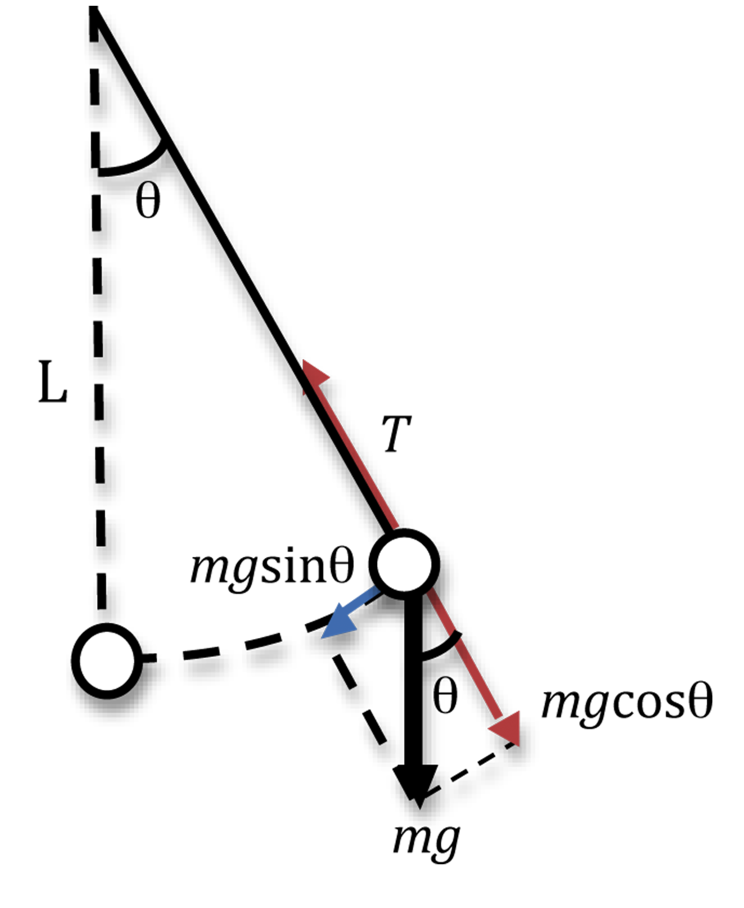

 Looking at the force diagram above, it is easy to show that the position of the bob on the pendulum can be described with the following equations.


$$-g\;\sin \;\theta =L\;\theta^¨ \;\;\;\;\;\;\;\;\to \;\;\;\;-g\;\theta =L\;\theta^¨$$
  

This can be manipulated to find theta as a function of time.


$$\theta =A\;\cos \;\textrm{Bt}\;\;\;\;\;\to \;\;$$

$$B=\sqrt{\frac{g}{L}\;}\;\;\;\;\;\;\;\;\to$$
     
$$\theta =A\;\cos \;\sqrt{\frac{g}{L}}\mathrm{t}\;\;\;\;\;\;\;\;\;\to$$
      
$$\theta =\theta_{\max } \;\cos \;\sqrt{\frac{g}{L}}\mathrm{t}$$


Matlab can find this analytical solution with ease. 

syms g L q_o q(t);
% Define first and second derivatives, and equation to be solved
Dq = diff(q, t);
D2q = diff(q, t, 2);
equ = D2q == - (g/L)*(q);
% Specify initial conditions q(o), Dq(0)
cond = [q(0) == q_o, Dq(0) == 0];
dsolve(equ, cond)

$$ans = \frac{q_{o}\,{\mathrm{e}}^{\frac{t\,\sqrt{-L\,g}}{L}}}{2}+\frac{q_{o}\,{\mathrm{e}}^{-\frac{t\,\sqrt{-L\,g}}{L}}}{2}$$

Some simple complex arithmatic will show this solution to be equal to  $\theta =\theta_{\max } \;\cos \;\sqrt{\frac{g}{L}}\mathrm{t}$

The equation above was just an approximation that works in the realm of small angles. In real life, pendulums don't conveniently oscillate as perfect sine waves. 

#### Example: Pendulum with No Analytical Solution

So what if we wanted to describe the actual equation of motion for the pendulum? The equation descibing the motion of the pendulum system would be more like this.

####  
$$\theta^¨ \;\left(t\right)=-\mu \theta^˙ \;\left(t\right)-\frac{g}{L}\;\sin \left(\theta \left(t\right)\right)$$


Where $\mu$ is an coefficient to describe air resistance, which in this case we model to be proportional to the velocity. This differential equation - like many encountered in physics - has no analytic solution. Thankfully, computational methods allows us to understand such equations without needing to find an exact analytical solution.

## The Basics of Numerical Methods for Solving Differential Equations

Before we apply computational methods to the pendulum problem above, its helpful to first look into how these methods work, and the different numerical techniques that can be used in Matlab. If we want to solve a differential equation, and we have some initial conditions $y_o$ and a period of time over which we want to obtain the answer $t_o ,t_f$, then a numerical solver can use the information at each step to estimate what the equation will look like at the next step. The smaller the step size, the closer the numerical solution will be to the exact solution. With this approach there is a fundamental tradeoff between efficiency and accuracy - smaller step sizes mean more computations, but better accuracy, and larger step sizes mean less computations but less accuracy. 

#### Example: Euler's Method

Euler's method is one of the most basic numerical methods for solving differential equations, and provides a good illustration of this tradeoff, as well as the basic underlying mechanisms at play. Going from step $f\left(y_n ,t_n \right)$ to step $f\left(y_{n+1} ,t_{n+1} \right)$, with a step size $h$, the algorithm uses the following.

               
$$s_1 =f\left(t_n ,y_n \right)$$
         
$$s_2 =f\left(t_n +\frac{h}{2},\;y_n +\frac{h}{2}s_1 \right)\;\;\;\;\;\;\;\;\Rightarrow$$
      
$$y_{n+1} =y_n +hs_2$$
     
$$t_{n+1} =t_n +h$$


As an example, take the differential equation $\frac{\textrm{d}}{\textrm{d}t}y=-2{\mathrm{te}}^{-t^2 }$, which has an exact solution of $y=e^{-t^2 } -1$. The code below shows the numerical solution to this differential equation using different step sizes, plotted along side the exact solution.

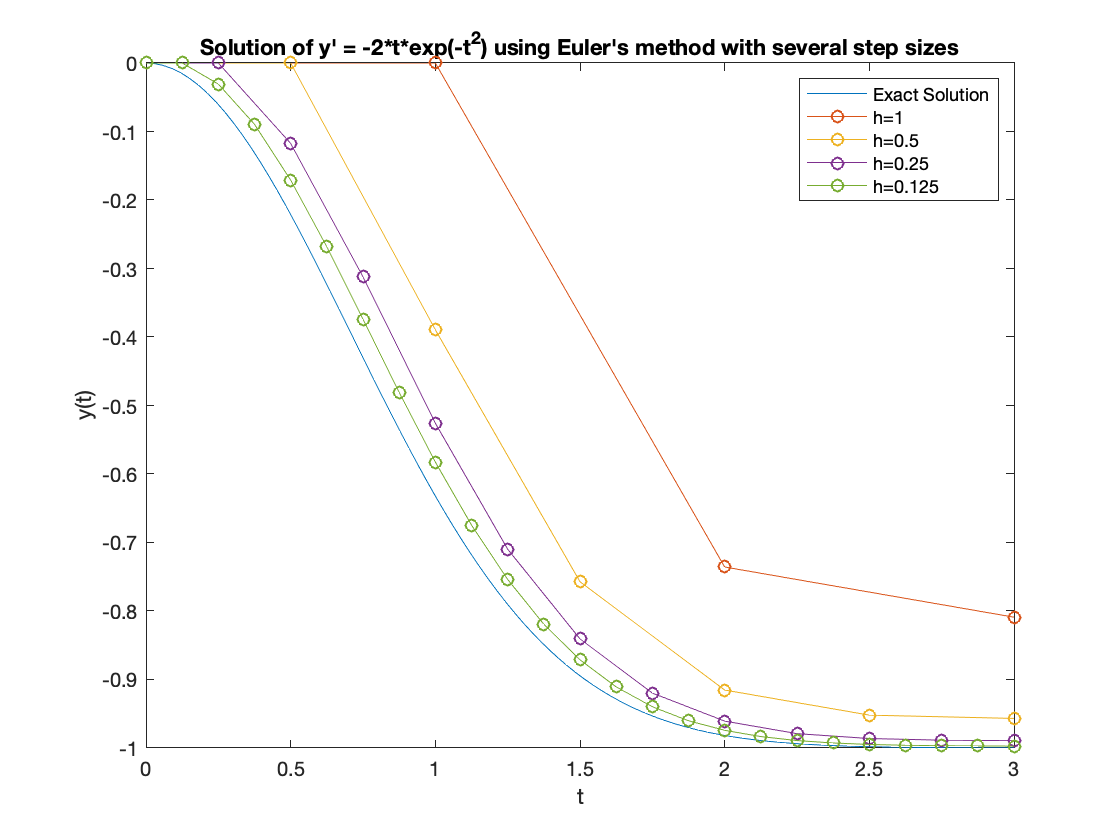

% code modified from 
% https://blogs.mathworks.com/loren/2015/09/23/ode-solver-selection-in-matlab/
clear, clc
h = 1;
tspan = [0 3];
f = @(t,y) -2*t*exp(-t.^2);
dydt(1) = 0;
t(1) = 0;

y = @(t) exp(-t.^2) - 1;
x = linspace(0,tspan(end));
figure
plot(x,y(x))
xlabel('t'), ylabel('y(t)')
hold on

while h > 0.1
    for k = 2:tspan(end)/h+1
        dydt(k) = dydt(k-1) + h*f(t(k-1),dydt(k-1));
        t(k) = t(k-1) + h;
    end

    plot(t,dydt,'-o')
    h = h/2;
end
legend('Exact Solution', 'h=1','h=0.5','h=0.25','h=0.125',...
    'Location','NorthEast')
title('Solution of y'' = -2*t*exp(-t^2) using Euler''s method with several step sizes')

## Matlab's ODE Solver Techniques

The numerical techniques used by Matlab are slightly more sophisticated than Euler's method, and involve calculating intermittant slopes between each step to get a better idea of what the function is doing within each interval. In addition, some algorithms estimate the error in each step to determine how big the next step should be. Ultimately, each numerical solver in Matlab represents a different tradeoff between accuracy and efficiency. 

ODE45 is the go-to numerical solver for most differential equations. It works by evaluating the slope four times between each step using the following process. 

   
$$s_1 =f\left(t_n ,y_n \right)$$
   
$$s_2 =f\left(t_n +\frac{h}{2},\;y_n +\frac{h}{2}s_1 \right)$$
   
$$s_3 =f\left(t_n +\frac{h}{2},{\;y}_n +\frac{h}{2}s_2 \right)$$
   
$$s_4 =f\left(t_n +\;h,{\;y}_n +hs_3 \right)$$


   
$$y_{n+1} =y_n +\frac{h}{6}\left(s_1 +2s_2 +2s_3 +s_4 \right)$$


   
$$t_{n+1} =t_n +h$$


The script below shows what happens when ODE45 is used on the differential equation  $\frac{\textrm{d}}{\textrm{d}t}y=-2{\mathrm{te}}^{-t^2 }$

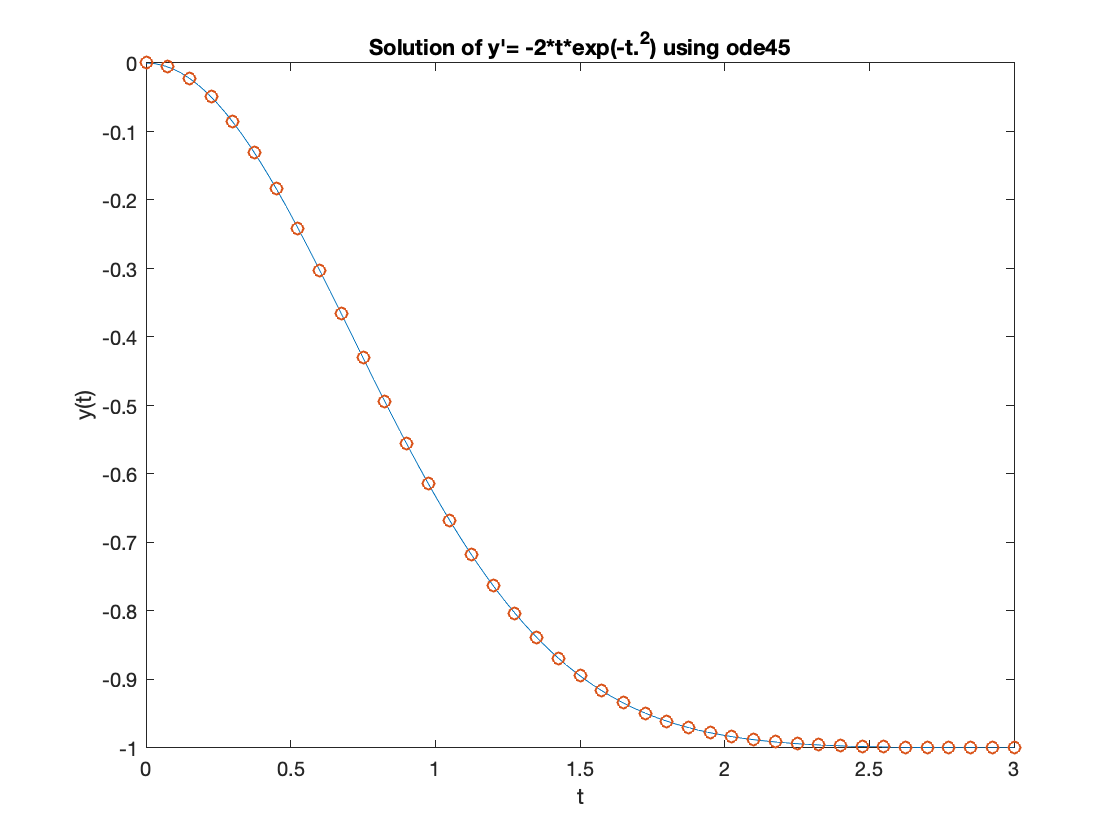

clear, clc
y = @(t) exp(-t.^2) - 1;
x = linspace(0,3);
figure
plot(x,y(x))
xlabel('t'), ylabel('y(t)')
hold on
[t,y] = ode45(@(t,y) -2.*t.*exp(-t.^2), [0 3], 0);
plot(t,y,'o')
xlabel('t'), ylabel('y(t)')
title('Solution of y''= -2*t*exp(-t.^2) using ode45')
hold off

Notice how the steps are closer together in areas where the function is changing more rapidly. This is because ODE45 conveniently maximizes computational efficiency by adjusting the step sizes according to how fast the function is changing. 

For some ODE problems, however, the step size is taken down to such a small level that it may require millions of evaluations in short time intervals. These types of ODE's are said to be *stiff*, and Matlab has solvers that are specifically designed to handle them (ODE15s, ODE23s, ODE23t, ODE23tb). *Nonstiff *solvers such as ODE45, ODE23, and ODE113 can still be used on stiff equations, but they may take an unreasonably long amount of time. 

#### Back to the Pendulum Example - Numerical Methods for 2nd Order DE's

Since the oscillating pendulum is a second order differential equation, some extra work is required in order to solve it numerically with Matlab. We need to convert it into a set of two first order differential equations.

 
$$\theta^¨ \;\left(t\right)=-\mu \theta^˙ \;\left(t\right)-\frac{g}{L}\;\sin \left(\theta \left(t\right)\right)$$
     
$$\Longrightarrow$$
         
$$\frac{d}{\mathit{dt}}\left\lbrack \begin{array}{c}
\theta \left(t\right)\\
\theta^˙ \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\theta^˙ \left(t\right)\\
\theta^¨ \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\theta^˙ \left(t\right)\\
-\mu \theta^˙ \;\left(t\right)-\frac{g}{L}\;\sin \left(\theta \left(t\right)\right)
\end{array}\right\rbrack$$


A phase diagram helps to see why this is the case. In the picture below on the left (from a 3Blue1Brown video cited at the end), the white dot represents the "state" of our pendulum system at some angle $\theta$ and angular velocity $\theta^˙$. If you take the derivative at that point, you get a vector that is some function of the point itself, and which shows us how our system tends to change from any position. Notice how the derivative in the veritcal direction is of the phase diagram is $\theta^¨$, which can be re-written in terms of  $-\mu \theta^˙ \;\left(t\right)-\frac{g}{L}\;\sin \left(\theta \left(t\right)\right)$. 

If we call our phase state by the abstract vector $\overrightarrow{X}$, then the derivative of this vector $\dot{\overrightarrow{X} }$ can be described by the coordinates.

$\dot{\overrightarrow{X} }$ = $\left\lbrack \begin{array}{c}
\theta^˙ \left(t\right)\\
-\mu \theta^˙ \;\left(t\right)-\frac{g}{L}\;\sin \left(\theta \left(t\right)\right)
\end{array}\right\rbrack$ 

This is now a pair of first order differential equations, with most of the important information encapsulated in the second term.

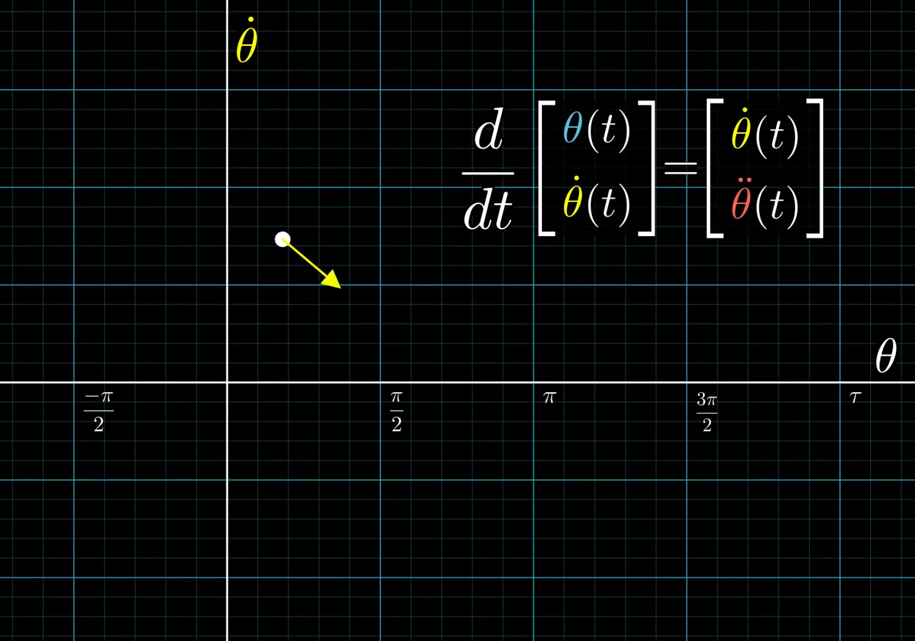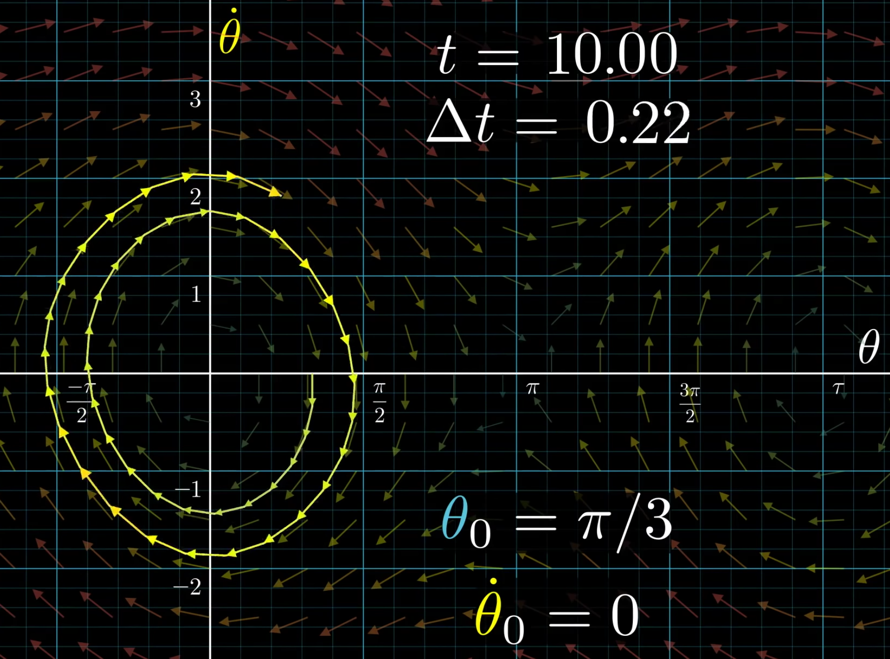

Now that we have the differential equation in the form of two single order equations, Matlab can compute a solution given some initial conditions $\theta_o \;$and $\dot{\theta_o }$, and a period of time over which we want to obtain the answer $\left.{\left(t\right.}_o \;,\;t_f \right)$. To do this, it uses the following basic principle: starting at some point in the phase diagram $\overrightarrow{X}$, a step is taken in the direction of the gradient of that vector $\dot{\overrightarrow{X} }$  for a small time step $\Delta t$.  Specifically, that step is equal to $\Delta t*\dot{\overrightarrow{X} \;}$. The picture on the right shows a (very inaccurate) description of how the state of the pendulum system evolves over a 10 second time interval with a (very large) time step of $\Delta t=0\ldotp 25s$. 

To solve the pendulum equation in Matlab (or any $\mathrm{Nth}$ order differential equation with $N\ge 2$), you can follow the basic process outlined below.  

***Step 1: Define Initial Conditions and Time Interval***

theta_0 = pi/3; % radians
theta_dot_0 = 0; % radians/second
tspan = [0 20]; % seconds

***Step 2: Decompose ***$\mathit{\mathbf{Nth}}$***Order DE into ***$\mathit{\mathbf{N}}$** First Order***** DE's***

To do this, we need to make a seperate function which decomposes the equation into a vector $\dot{\overrightarrow{X} }$ of $N$ first order equations. To reuse code, it is useful to define this function in a separate `.m `file. For the pendulum example, this function is contained in the file `pendode_w_drag.m. `

***Step 3: Input Decomposition Function, Initial Conditions, and Time Interval into ODE Function***

[t, y] = ode45(@pendode_w_drag, tspan, [theta_0; theta_dot_0]);

Finally, we can plot the vector `[t, y(:,1)] `to show how the position of the pendulum evolves over time. 

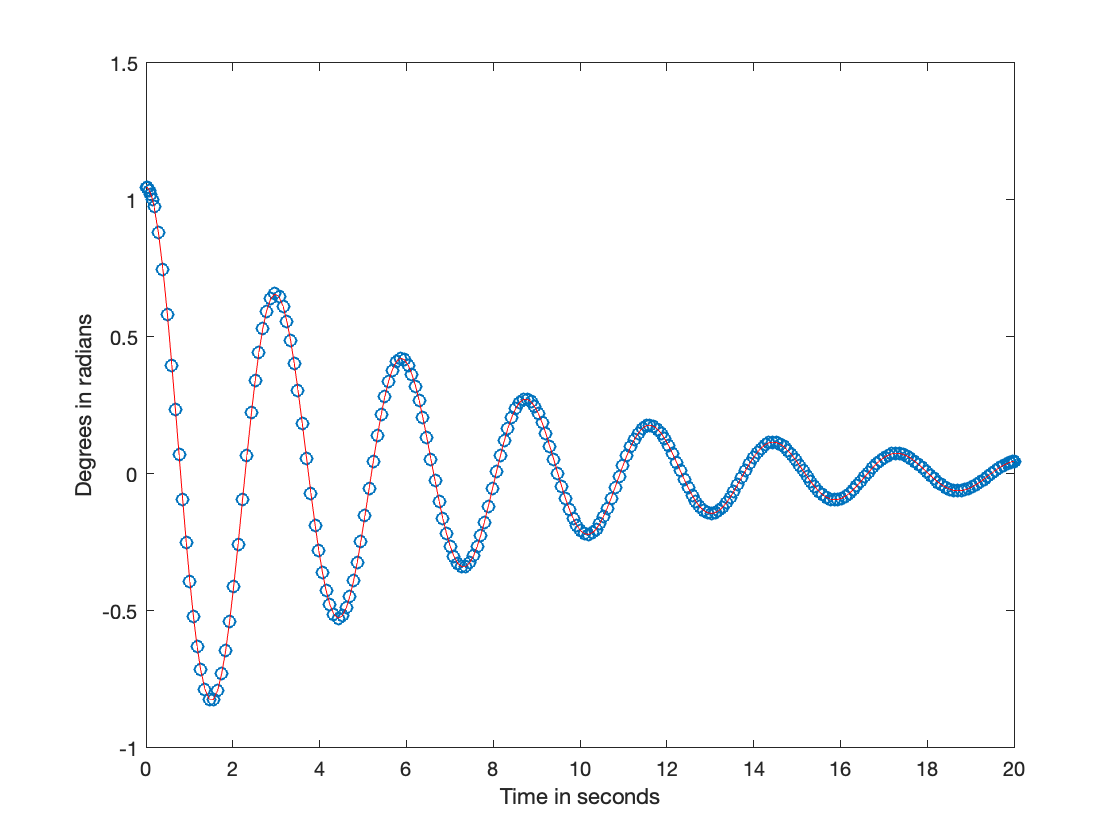

plot(t, y(:,1), 'o',t, y(:,1), '-r')
xlabel('Time in seconds')
ylabel('Degrees in radians')

## Comparason of Numerical Approaches

To see how ODE45 compares to other numerical approaches, we can plot the different solutions side-by-side.

 
Stats for ode45:
62 successful steps
1 failed attempts
379 function evaluations
Elapsed time is 0.010342 seconds.
 
Stats for ode15s:
150 successful steps
5 failed attempts
266 function evaluations
1 partial derivatives
23 LU decompositions
262 solutions of linear systems
Elapsed time is 0.049838 seconds.
 
Stats for ode23:
209 successful steps
25 failed attempts
703 function evaluations
Elapsed time is 0.014210 seconds.
 
Stats for ode113:
134 successful steps
4 failed attempts
273 function evaluations
Elapsed time is 0.050045 seconds.


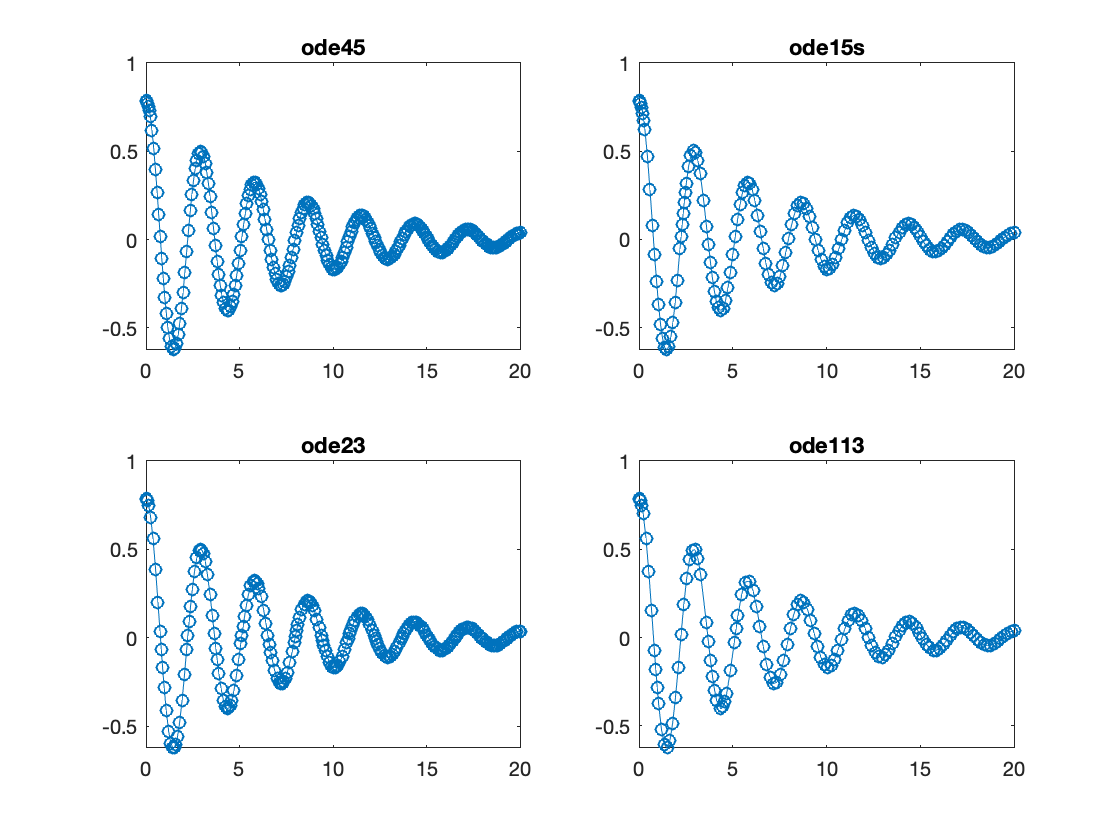

pendulumODE

All of the solvers performed nicely, but they varied significantly in execution time. Notice how ode15s (which is optimized for stiff equations) took almost 10 times as long while producing a less accurate solution (less function evaluations).

function pendulumODE
opts = odeset('stats','on');
tspan = [0 20];
y0 = [pi/4, 0];

disp(' '), disp('Stats for ode45:')
tic, [t1,y1] = ode45(@pendode_w_drag, tspan, y0, opts);
toc

disp(' '), disp('Stats for ode15s:')
tic, [t2,y2] = ode15s(@pendode_w_drag, tspan, y0, opts);
toc

disp(' '), disp('Stats for ode23:')
tic, [t3,y3] = ode23(@pendode_w_drag, tspan, y0, opts);
toc

disp(' '), disp('Stats for ode113:')
tic, [t4,y4] = ode113(@pendode_w_drag, tspan, y0, opts);
toc

figure
subplot(2,2,1), plot(t1,y1(:,1),'-o'), xlim([0 20]), title('ode45')
subplot(2,2,2), plot(t2,y2(:,1),'-o'), xlim([0 20]), title('ode15s')
subplot(2,2,3), plot(t3,y3(:,1),'-o'), xlim([0 20]), title('ode23')
subplot(2,2,4), plot(t4,y4(:,1),'-o'), xlim([0 20]), title('ode113')
end




#### Sources

[https://www.webassign.net/question_assets/ncsucalcphysmechl3/lab_7_1/images/figure8.png](https://www.webassign.net/question_assets/ncsucalcphysmechl3/lab_7_1/images/figure8.png)

[https://blogs.mathworks.com/loren/2015/09/23/ode-solver-selection-in-matlab/](https://blogs.mathworks.com/loren/2015/09/23/ode-solver-selection-in-matlab/)

[https://youtu.be/p_di4Zn4wz4](https://youtu.be/p_di4Zn4wz4)